# Amplifiers 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction 

This notebook provides an introduction to operational amplifiers and models for a:

- Differential Amplifier

- Instrumentation Amplifier

- Charge Amplifier 

- Transimpedance Amplifier 

- Programmable Gain Amplifier 

## Differentiator

## Differential Amplifier

A simple model for a differential amplifier is created and shown in figure below. The amplifier is extremely sensitive to the imbalance of the resistor values and therefore it is critical that R3/R1=R4/R2 in both branches of the amplifier is equal. 

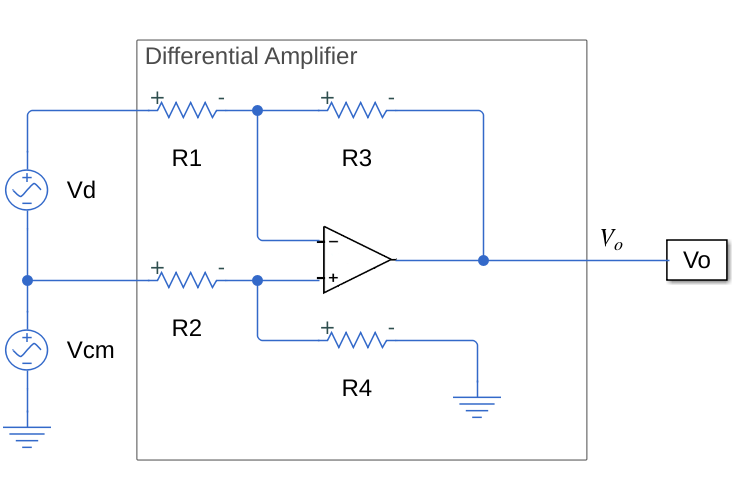

Differential amplifiers amplifies the difference between the input voltages. For the selected values of resistors, the output of this circuit is 10 times larger than the difference between inputs. Resistors have the following values : R1=10 kΩ, R2=100 kΩ, R3=10 kΩ and R4=100 kΩ.  For the input voltage difference of 0.2 V, the output is 2 V. 

The differential amplifier equation is as follows when R1=R3 and R2=R4: 


$$V_{\textrm{out}} =\frac{R_2 }{R_1 }\left(V_{\textrm{diff}} \right)$$


For the example, if Vin =0.2 V and for the other parameters of the model belo we get: 


$$V_{\textrm{out}} =\frac{100}{10}\left(0\ldotp 2\right)=2V$$


The simulation input and output can be seen in a graph as well: 

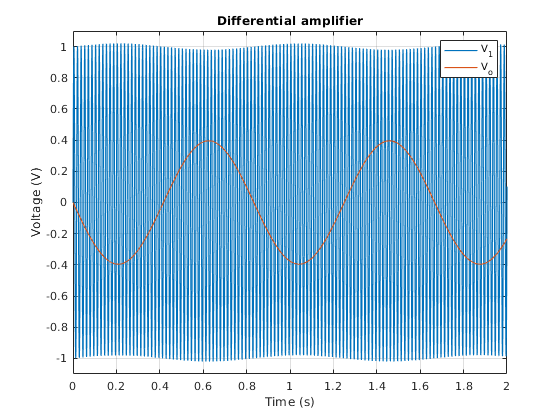

set_param('Differential_amplfier/R1','R','10');
set_param('Differential_amplfier/R2','R','10');
set_param('Differential_amplfier/R3','R','100');
set_param('Differential_amplfier/R4','R','100');
set_param('Differential_amplfier/R3','enable_R_tol','0');
model_name = 'Differential_amplfier';
open_system(model_name);
sim(model_name)


% Get simulation results
temp_vin = simout.Data(:,1);
temp_vout = simout.Data(:,2);

% Plot results
figure
plot(simout.Time,temp_vin,'LineWidth',1);
hold on
plot(simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Differential amplifier');
ylabel('Voltage (V)');
xlabel('Time (s)');
ylim([-1.1,1.1])
xlim([0,2])
legend({'V_1','V_o'});

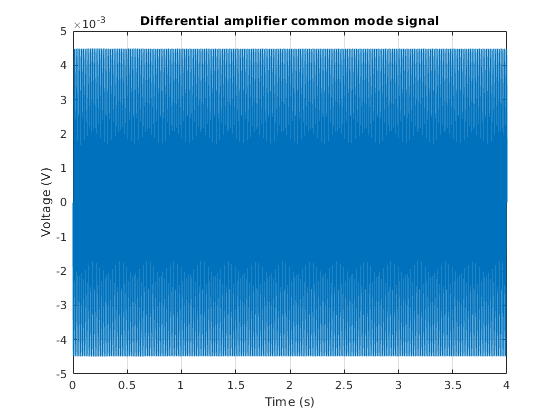


set_param('Differential_amplfier/R3','enable_R_tol','2');
set_param('Differential_amplfier/R3','R_tol','0.5'); % 0.5 was used for 1% tolerance. Please use 0.05 and 0.005 for Table 1
set_param('Differential_amplfier/Vd//2','amp','0');
set_param('Differential_amplfier/-Vd//2','amp','0');
sim(model_name)
% Get simulation results
temp_vin = simout.Data(:,1);
temp_vout = simout.Data(:,2);

% Plot results
figure
%plot(simout.Time,temp_vin,'LineWidth',1);
%hold on
plot(simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Differential amplifier common mode signal');
ylabel('Voltage (V)');
xlabel('Time (s)');

ampl_CM=max(simout.Data(500:end,2));
disp ('CMRR for 1% tolerance from Ad=10 is:') % Please note that the values in Table 2 are computed for Ad=1;

CMRR for 1% tolerance from Ad=10 is:


CMRR=mag2db(10/ampl_CM)

CMRR = 66.9589

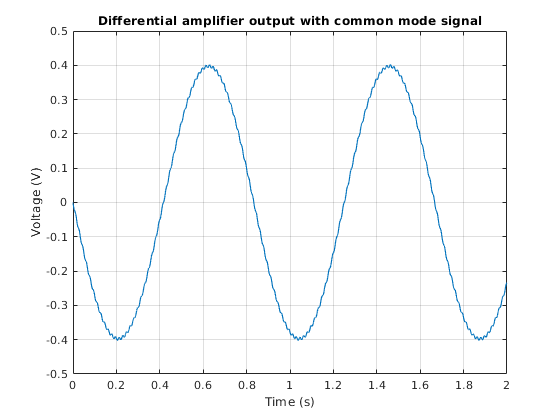


set_param('Differential_amplfier/R3','enable_R_tol','2');
set_param('Differential_amplfier/R3','R_tol','0.5'); % 0.5 was used for 1% tolerance. Please use 0.05 and 0.005 for Table 1
set_param('Differential_amplfier/Vd//2','amp','0.02');
set_param('Differential_amplfier/-Vd//2','amp','0.02');
sim(model_name)
% Get simulation results
temp_vin = simout.Data(:,1);
temp_vout = simout.Data(:,2);

% Plot results
figure
%plot(simout.Time,temp_vin,'LineWidth',1);
%hold on
plot(simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Differential amplifier output with common mode signal');
xlim([0,2])
ylabel('Voltage (V)');
xlabel('Time (s)');

%ylim([-1.5,1.5])
%legend({'Input','Output'},'Location','Best');


Both obtained and expected outputs are same.

**Bonus example: Derive the differential amplifier equation **

## Instrumentation Amplifier

The most basic and wide-use instrumentation amplifier is usually developed by using three op amps, the model created can be seen below. 

For the selected values of resistors, the output of this circuit is 3 times larger than the difference between inputs. Resistors have the following values : R1=1 kΩ, R2=1 kΩ, R3=1 kΩ, R4=1 kΩ R5=1 kΩ, R6=1 kΩ, R7=1 kΩ.  For the input voltage difference of 10 V, the output is 30V. 

The instrumentation amplifier equation is as follows when R1=R2, R2=R4, and R6=R7: 


$$V_{\textrm{out}} =\left\lbrack \left(1+\left(\frac{{2R}_1 }{R_3 }\right)\right)*\frac{R_7 }{R_4 }\right\rbrack \left(V_{\textrm{diff}} \right)$$


For the example model: 


$$V_{\textrm{out}} =\left\lbrack \left(1+\left(\frac{2*1}{1}\right)\right)*\frac{1}{1}\right\rbrack \left(10\right)$$



$$V_{\textrm{out}} =\left(3\right)\left(10\right)=30V$$
 

The simulation input and output can be seen in a graph as well: 

model_name = 'instrumentation_amplifier';


open_system(model_name);
sim(model_name)

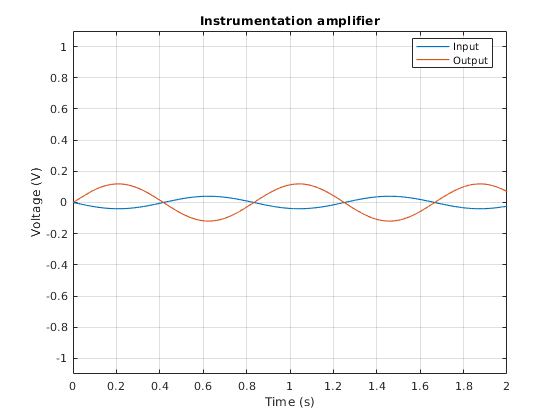



% Get simulation results
temp_vin = simout.Data(:,1);
temp_vout = simout.Data(:,2);

% Plot results
figure
plot(simout.Time,temp_vin,'LineWidth',1);
hold on
plot(simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Instrumentation amplifier');
ylabel('Voltage (V)');
xlabel('Time (s)');
ylim([-1.1,1.1])
xlim([0,2])
legend({'Input','Output'},'Location','Best');

Both obtained and expected outputs are same. 

In general, the three-op instrumentation amplifier has a potential for a large gain for input differential signals, while the gain for common-mode signals is always 1. The  CMRR is equal to Differential Gain, which can be adjusted by changing the gain resistor (R6). Therefore, this kind of circuit can efficiently reject 60Hz noise in measurement, and has been widely used in biopotential instrumentation. 

## Demodulator

The simulation does not work at the moment.

open_system('demodulator')
simOut = sim('demodulator', 'CaptureErrors', 'on');
plot(out.simout.Data(:,3))

## Charge Amplifier 

This example provides introduction to the charge amplifier circuit connected to the model of the piezoelectric transducer. This circuit is based on Analog Devices application note: [12-Bit, 1 MSPS, Single-Supply, Two-Chip Data Acquisition System for Piezoelectric Sensors](https://www.analog.com/media/en/reference-design-documentation/reference-designs/CN0350.pdf). 

plotting=1;
start_time=1000;

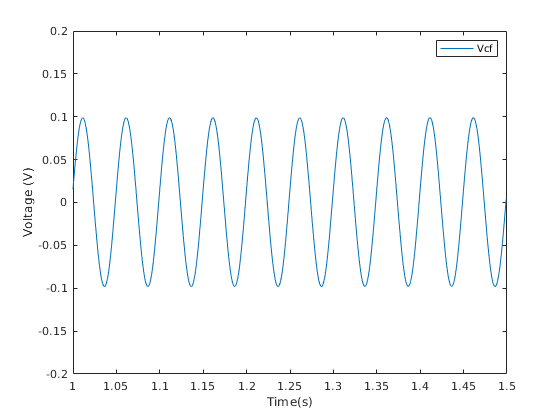

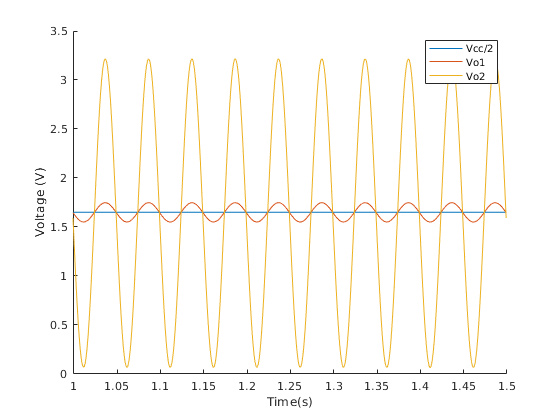

end_time=1500;
open_system('ChargeAmpl1')
simout = sim('ChargeAmpl1', 'CaptureErrors', 'on');

Plotting results:

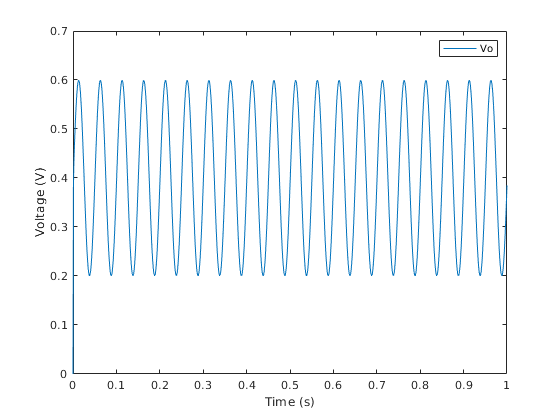

if plotting ==1
    figure
    plot(simout.VCf.Time(start_time:end_time), simout.VCf.Data(start_time:end_time))
    xlabel("Time(s)")
    ylabel("Voltage (V)")
    xlim([1,1.5]);
    ylim([-0.2,0.2])
    legend("Vcf");
    %figure
    %plot(i.Time(start_time:end_time), i.Data(start_time:end_time))
    figure

    hold on, plot(simout.VCf.Time(start_time:end_time), 1.65*ones(1,end_time-start_time+1))
    plot(simout.Vo1.Time(start_time:end_time), simout.Vo1.Data(start_time:end_time))
    plot(simout.Vo2.Time(start_time:end_time), simout.Vo2.Data(start_time:end_time)) 
    xlabel("Time(s)")
    ylabel("Voltage (V)")
    legend("Vcc/2","Vo1","Vo");
    xlim([1,1.5])
end


## Transimpedance Amplifier 

plotting=1;
open_system('Transimpedance')
simout = sim('Transimpedance', 'CaptureErrors', 'on');
if plotting ==1
    figure
    plot(simout.Vo.Time, simout.Vo.Data)
    xlabel("Time (s)")
    ylabel("Voltage (V)")
    legend("Vo");
    ylim([0,0.7])
end    

## Programmable Gain Amplifier 

Programmable gain amplifiers (PGA) commonly have a set of values of gains that can be digitally programmed or set by a microcontroller or a microprocessor. PGAs are used nowadays in biomedical instrumentation in general, as a photodiode amplifier circuits, as ultrasound and sonar preamplifiers and so on. 

PGAs are very important in applications where the signal level can vary significantly and can cause the signal at the output of the amplifier to be either too small or to saturate. They are often used as a part of signal conditioning circuit before A/D converter to make sure that the full range of A/D/ converter is covered.

A simple model for a PGA is created and shown in figure below. 

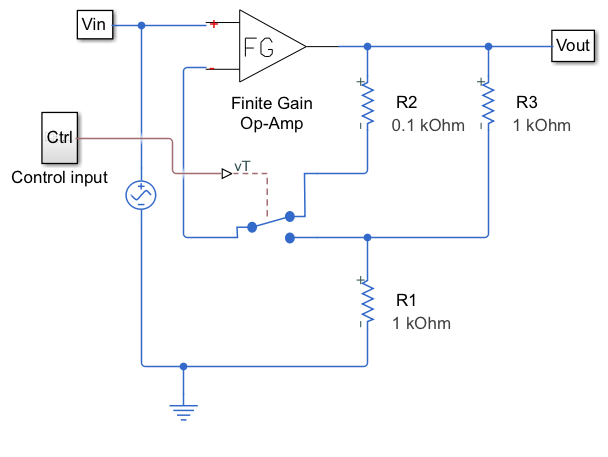

The PGA has only one control input that can be set to either 0 V or 5 V. When it is set to 0 V, the switch is up as shown in the figure and the gain is 1. When the control input is set to 5V, the amplifier is acting as non-inverting amplifier and the gain is 1+R3/R1=2. This setup of the PGA is used in order to remove the effect of the finite resistance of the switch when the switch is ON [AD08].

The simulation input and output can be seen in a graph as well: 

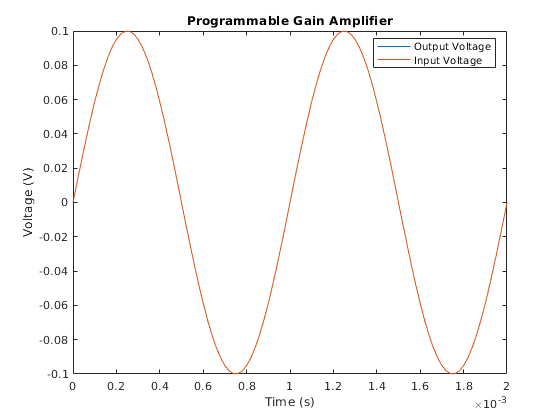

model_name = 'pga';
open_system(model_name);


%Set control input to either 0V or 5V
set_param('pga/Control input/Constant','Value','0')

sim(model_name)

% Plot results
figure
plot(ScopeData1.time,ScopeData1.signals.values)

hold on

title('Programmable Gain Amplifier')
ylabel('Voltage (V)')
legend({'Output Voltage', 'Input Voltage'},'Location','Best');
xlabel('Time (s)');

It can be seen that when it is set to 0 V, the switch is up and the gain is 1. 

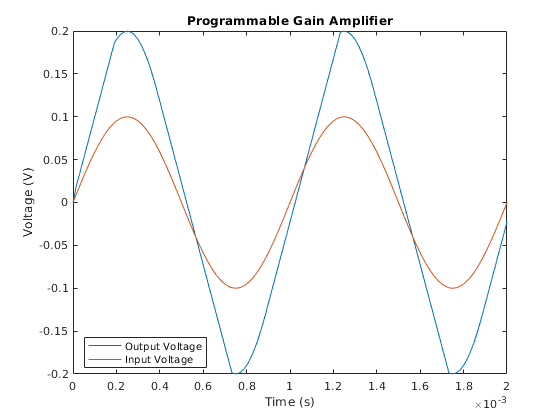

model_name = 'pga';
open_system(model_name);



%Set control input to either 0V or 5V
set_param('pga/Control input/Constant','Value','5')
sim(model_name)

% Plot results
figure
plot(ScopeData1.time,ScopeData1.signals.values)


hold on

title('Programmable Gain Amplifier')
ylabel('Voltage (V)')
legend({'Output Voltage', 'Input Voltage'},'Location','Best');
xlabel('Time (s)');

xlim([0.00000 0.00200])
ylim([-0.200 0.200])

It can be seen that when it is set to 5 V, the switch is up and the gain is 2. 